% (C) Copyright 2020 Murilo Marques Marinho
%
%     This file is licensed in the terms of the
%     Attribution-NonCommercial-ShareAlike 4.0 International (CC BY-NC-SA 4.0) 
%     license.
%
% Contributors to this file:
%     Murilo Marques Marinho - murilo@nml.t.u-tokyo.ac.jp

# Optimization-Based Robot Control using DQ Robotics

## Introduction

In the last lesson, you learned how model robotic manipulators parameterized using the DH parameters. You also learned how to use a basic controller based on the pseudo-inverse of the task Jacobian.

That was an introductory exposition to robot control, and in this lesson we will understand somewhat better how robot control works using concepts of quadratic optimization.

## Notation

Keep these in mind (we will also use this notation when writting papers to conferences and journals):

- $\mathit{\mathbf{h}}\in$$\mathbb{H}$: a quaternion. (Bold-face, lowercase character)

- $\underline{\mathit{\mathbf{h}}} \in$$\mathcal{H}$: a dual quaternion. (Bold-face, underlined, lowercase character)

- $\mathit{\mathbf{p}},\mathit{\mathbf{t}},\cdots \in$$$\mathbb{H}_p$$: pure dual quaternions. They represent points, positions, and translations. They are quaternions for which $\textrm{Re}\left(\mathit{\mathbf{h}}\right)=0\ldotp$

- $\mathit{\mathbf{r}}\in$$\mathbb{S}^3$: unit quaternions. They represent orientations and rotations. They are quaternions for which $\left|\right|\mathit{\mathbf{h}}\left|\right|=1$. 

- $\underline{\mathit{\mathbf{x}}}$ $\in$$\underline{\mathcal{S}}$: unit dual quaternions. They represent poses and pose transformations. They are dual quaternions for which $\left|\right|\underline{\mathit{\mathbf{h}}} \left|\right|=1$.

- $\underline{{\bf l}}\in \mathcal{H}_p\cap$$\underline{\bf{\mathcal{S}}}$: a Plücker line. 

- $\pi_‾$ $\in \left\lbrace \right.$$P\left(\pi_‾ \right)\in$ $$\mathbb{H}_p$$$\left.\right\rbrace$$\cap \;$$\underline{\bf{\mathcal{S}}}$: a plane.

## Robot definition

The concepts of this lesson apply to any manipulator robot. However, to have a more concrete understanding using DQ Robotics, consider the following robot that will be used in all examples in this lesson.

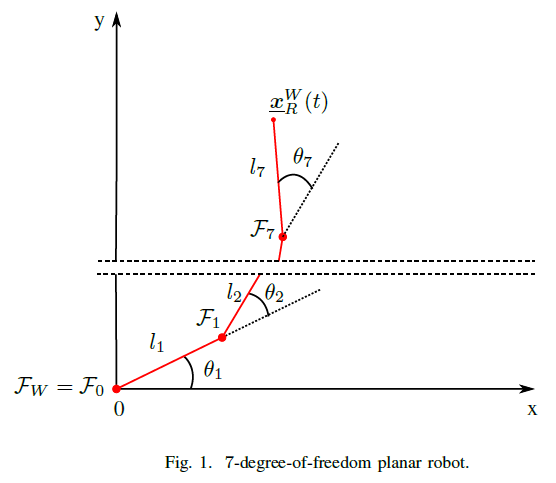

- Let the robot $R$ be a 7-DoF planar robot, as draw in Fig.1. 

- Let $\mathcal{F}_W$ be the world-reference frame. 

- Let $\underline{\bf{x}}_R(t)\triangleq\underline{\bf{x}}_R$ $\in$$\underline{\mathcal{S}}$ represent the pose of the *end effector*. 

- Let $R$ be composed of seven rotational joints that rotate about their z-axis, composed in the joint-space vector ${\bf q}\left(t\right)\triangleq{\bf q}=\left[\theta_{1}\ \theta_{2}\ \theta_{3}\ \theta_{4}\ \theta_{5}\ \theta_{6}\ \theta_{7}\right]^{T}$ with $\theta_{i}\left(t\right)\triangleq\theta_{i}\in\mathbb{R}$ for $i=1,2,\ldots,7$. The rotation of the reference frames of each joint coincide with the rotation of $\mathcal{F}_W$ when $\theta_{i}=0$. The length of the joint are $l_i \in$$\mathbb{R}^+-\{0\}$.

- Consider that we can freely control the joint vector ${\bf q}$.

This robot can be modeled by the following class.

Let us instante our robot as follows

seven_dof_planar_robot = SevenDofPlanarRobotDH.kinematics();

## Robot controller

The concepts of this lesson also apply for any of the task-space control types mentioned in the last lesson (and others). For us to have a concrete example for this class, let us define a translation controller based on the pseudo-inverse of the Jacobian with no damping.

translation_controller = DQ_PseudoinverseController(seven_dof_planar_robot);
translation_controller.set_control_objective(ControlObjective.Translation)
translation_controller.set_gain(100)
translation_controller.set_damping(0)

## Task-space singularities

One important concept when controlling a robot using its task Jacobian is the concept of workspace singularities. The workspace singularities are closely related to the linear-algebra concept of singular matrices. Let us remem


$${\bf I}_{3\times3}= \left[\matrix{1 & 0 & 0 \cr 0 & 1 & 0 \cr 0 & 1 & 0 }\right]$$


I3_3 = eye(3)

I3_3 =      1     0     0
     0     1     0
     0     0     1


It obviously has rank three, that is, its three rows are linear independent.

rank(I3_3)

ans = 3

However, the following the matrix


$${\bf A}= \left[\matrix{0 & 0 & 1 \cr 0 & 0 & 1 \cr 0 & 1 & 0 }\right].$$


A = [0 0 1;
      0 0 1;
      0 1 0]

A =      0     0     1
     0     0     1
     0     1     0


It is obvious that its first and second row are linear dependent. Hence, it will be of rank two.

  rank(A1)

ans = 2

A square matrix is considered singular whenever its rank is lower than its number of rows. This means that the matrix does not have an inverse.

### A quick review on the Moore-penrose pseudo-inverse

For any full-rank matrix ${\bf A}^{m\times n}, \text{rank}({\bf A})=m$ (which includes non-square ones), a very convenient way to "invert" them is to use the Moore-penrose pseudo-inverse. For convenience, let us restrict the examples for matrices in which $m\leq n$.


$${\bf A}= \left[\matrix{2 & 0 & 1 & 2 \cr 0 & 0 & 1 & 4 \cr 0 & 1 & 0 & 5  }\right].$$


  A = [2 0 1 2;
      0 0 1 4;
      0 1 0 5;]

A =      2     0     1     2
     0     0     1     4
     0     1     0     5


  rank(A)

ans = 3

As you might remember, every real matrix can be decomposed as follows


$${\bf A} = {\bf U}{\bf \Sigma}{\bf V}^T$$


where ${\bf U}\in\mathbb{R}^{m \times m}$ and ${\bf V}\in\mathbb{R}^{n \times n}$ are orthogonal matrices (i.e., they are square, full rank, and their inverses are given by ${\bf U}^{-1}={\bf U}^T$ and ${\bf V}^{-1}={\bf V}^T$). Moreover, ${\bf \Sigma}$ is a (rectangular) diagonal matrix composed of the singular values of the matrix given by $\sigma_i$ for $i=1,\ldots,m$, ordered from the largest singular value towards the smallest singular value. Note that singular values are always non-negative. 

Given that ${\bf \Sigma}$ always has the same dimensions of the original matrix, when the matrix is square, its corresponding ${\bf \Sigma}$ will be square


$${\bf \Sigma} = \left[ \matrix
{\sigma_1 & 0 & \cdots  & 0 \cr
0 & \sigma_2 & \dots & 0 \cr
0 & \vdots & \ddots & 0 \cr
0 & 0 & 0 & \sigma_m
 } \right]$$


When the matrix is rectangular, its corresponding ${\bf \Sigma}$ will be rectangular, for instance


$${\bf \Sigma} = \left[ \matrix
{\sigma_1 & 0 & \cdots  & 0 & 0\cr
0 & \sigma_2 & \dots & 0 & 0\cr
0 & \vdots & \ddots & 0 & 0\cr
0 & 0 & 0 & \sigma_m & 0
 } \right]$$


With these properties, a pseudo-inverse can be defined for any matrix for which all singular values are non-zero. That inverse is given by


$${\bf A}^\dagger={\bf V}^T{\bf \Sigma}^{\text{inv}} {\bf U}^T$$


where ${\bf \Sigma}^{\text{inv}}$ is a compatible matrix where we use the reciprocate of the singular values. For example, for a square matrix we have


$${\bf \Sigma}^{inv} = \left[ \matrix
{\frac{1}{\sigma_1} & 0 & \cdots  & 0 \cr
0 & \frac{1}{\sigma_2} & \dots & 0 \cr
0 & \vdots & \ddots & 0 \cr
0 & 0 & 0 & \frac{1}{\sigma_m}
 } \right]$$


and for a rectangular matrix


$${\bf \Sigma}^{inv} = \left[ \matrix
{\frac{1}{\sigma_1} & 0 & \cdots  & 0\cr
0 & \frac{1}{\sigma_2} & \dots & 0 \cr
0 & \vdots & \ddots & 0 \cr
0 & 0 & 0 & \frac{1}{\sigma_m} \cr
0 & 0 & 0 & 0
 } \right]$$


Then, we find that


$${\bf \Sigma} {\bf \Sigma}^{inv}= {\bf I}_{m\times n}.$$


Therefore, we find that


$${\bf A}{\bf A}^\dagger= {\bf U}{\bf \Sigma}{\bf V}^T{\bf V}^T{\bf \Sigma}^{\text{inv}} {\bf U}^T$$



$${\bf A}{\bf A}^\dagger= {\bf I}_{m\times m}$$


and, conversely


$${\bf A}{\bf A}^\dagger= {\bf I}_{n\times n}.$$


This inverse has several interesting properties that we will discuss when they are needed.

### A quick review on the SVD-based inverses

In practice, we want our algorithm to be able to invert even non-singular matrices. Let ${\bf B}^{m\times n}$ be such that $\text{rank}({\bf B})=r< m$. For convenience, let us restrict the examples for matrices in which $m\leq n$.

The SVD-based pseudo-invese is similar to the Moore-Penrose techinque, but 


$${\bf \Sigma}^{inv} = \left[ \matrix
{\frac{1}{\sigma_1} & 0 & \cdots  & 0 & \cdots & 0\cr
0 & \frac{1}{\sigma_2} & \dots & 0 & \cdots & 0 \cr
0 & \vdots & \ddots & 0 & \cdots & 0 \cr
0 & 0 & 0 & \frac{1}{\sigma_r} & \cdots & 0 \cr
\vdots & \vdots & \vdots & \vdots  & \ddots & 0\cr
0 & 0 & 0 & 0 & \cdots & 0
 } \right].$$


This means that when the pseudo-inverse is applied, the result will be


$${\bf B}{\bf B}^\dagger= \left[ \matrix{ {\bf I}_{r\times r} & {\bf 0}_{r\times (m-r)} \cr
{\bf 0}_{(m-r)\times r} & {\bf 0}_{(m-r)\times(m-r)}} \right]$$


and


$${\bf B}{\bf B}^\dagger= \left[ \matrix{ {\bf I}_{r\times r} & {\bf 0}_{r\times (n-r)} \cr
{\bf 0}_{(n-r)\times r} & {\bf 0}_{(n-r)\times(n-r)}} \right].$$
